## Espace de solutions suivant une trajectoire et qui respecte les butées articulaires et qui évite les singularitées du robot

**Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

On définit tout d'abord les variables du code puis l'espace de solutions sans conditions de filtrage pour atteindre le point cible est recupéré pour ensuite afficher les differentes configuration articulaires possibles en radian

% Charger les solutions depuis le fichier
load('finalresCIRand.mat');

fprintf('Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en RADIAN:\n');

Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en RADIAN:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(final_results_all_with_CIRand);

    1.0000    1.0000    5.2627    0.6615    0.5200    0.4918    0.0052    9.0000    0.0000
    1.0000    2.0000    0.1191    5.2836    1.6310    6.0665    6.1277    8.9391    1.0448
    1.0000    3.0000    0.0973    5.4642    1.6107    6.0783    6.1499    8.7574    2.0755
    1.0000    4.0000    0.0084    5.7558    1.5374    6.1079    6.1832    8.4572    3.0782
    1.0000    5.0000    6.0185    0.0880    1.2727    6.1675    6.2725    8.0427    4.0392
    1.0000    6.0000    6.1341    0.0884    1.2604    6.1675    0.0277    7.5194    4.9456
    1.0000    7.0000    6.2707    0.0542    1.2657    6.1652    0.0597    6.8944    5.7851
    1.0000    8.0000    0.1213    0.0253    1.2685    6.1633    0.0900    6.1762    6.5464
    1.0000    9.0000    0.2398    0.0224    1.2591    6.1630    0.1210    5.3744    7.2191
    1.0000   10.0000    0.3386    0.0531    1.2324    6.1650    0.1564    4.5000    7.7942
    2.0000    1.0000    5.1115    1.1896    0.8364    5.3000    0.4008    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------



final_results_all_with_CIRand(:, 3:7) = rad2deg(final_results_all_with_CIRand(:, 3:7));
final_results_all_with_CIRand(:, 3:7) = mod(final_results_all_with_CIRand(:, 3:7)+ 180, 360) - 180;

fprintf('Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en DEGRES:\n');

Résultats des diffrents sets de positions que peut avoir le robot pour suivre la trajectoire selon la position initiale en DEGRES:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(final_results_all_with_CIRand);

    1.0000    1.0000  -58.4668   37.8986   29.7935   28.1803    0.2963    9.0000    0.0000
    1.0000    2.0000    6.8224  -57.2715   93.4477  -12.4130   -8.9066    8.9391    1.0448
    1.0000    3.0000    5.5723  -46.9220   92.2836  -11.7412   -7.6388    8.7574    2.0755
    1.0000    4.0000    0.4827  -30.2173   88.0868  -10.0440   -5.7283    8.4572    3.0782
    1.0000    5.0000  -15.1634    5.0429   72.9178   -6.6306   -0.6096    8.0427    4.0392
    1.0000    6.0000   -8.5401    5.0642   72.2144   -6.6301    1.5884    7.5194    4.9456
    1.0000    7.0000   -0.7135    3.1046   72.5184   -6.7583    3.4228    6.8944    5.7851
    1.0000    8.0000    6.9495    1.4515   72.6796   -6.8671    5.1584    6.1762    6.5464
    1.0000    9.0000   13.7408    1.2820   72.1413   -6.8879    6.9311    5.3744    7.2191
    1.0000   10.0000   19.4001    3.0432   70.6090   -6.7740    8.9583    4.5000    7.7942
    2.0000    1.0000  -67.1308   68.1607   47.9244  -56.3327   22.9636    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------


## Filtrage des solutions

### CI pour laquelle toutes les solutions respectent la continuite, la singularite et les butees articulaires

Cette partie tri notre espace de solutions, en fonction des butées de chaque articulations et des positions de singularitées. De cette manière, nous pouvons observer dans la table ci-dessous les configurations (en gras), qui respectent bien ces deux conditions.

Ainsi, on a dans la derniere table le resultat final de notre espace de travail qui repond aux differentes conditions de filtrage des solutions 

disp('Butées de chaque theta:')

Butées de chaque theta:


% Chargement de la matrice butee à partir du fichier .mat
load('butee.mat'); % Charge la matrice butee à partir du fichier butee.mat
disp(butee);

   -90    90
   -95    95
   -90    90
   -90    90
   -90    90




% % Filtrage des solutions pour les butées articulaires
% trisolution = solutions_filtrees_continues(:, 3:7) >= butee(:, 1)' & solutions_filtrees_continues(:, 3:7) <= butee(:, 2)';
% 
% % Vérification des singularités pour les solutions filtrées
% singularite = check_singularities(deg2rad(solutions_filtrees_continues(:, 3:7)), a1, a2, a3, a4, a5);

% Initialiser le seuil de différence
seuil = 18; % Vous pouvez ajuster cela selon vos besoins

% Initialiser la CI respectée à une valeur qui n'existe pas dans vos données
ci_continuite = [];

% Initialiser une matrice pour stocker les CI où tous les points de la trajectoire respectent les critères
ci_all_points_valid = [];

% Initialiser une matrice pour stocker les solutions filtrées
solutions_filtrees_CI_complete = [];

% Pour chaque configuration initiale
for ci = 1:max(final_results_all_with_CIRand(:, 1))
    % Extraire les indices correspondant à cette configuration initiale
    indices = final_results_all_with_CIRand(:, 1) == ci;
    % Extraire les données pour cette configuration initiale
    data_for_ci = final_results_all_with_CIRand(indices, :);
    % Initialiser le drapeau pour suivre si la différence est respectée pour tous les points
    diff_respected = true;
    % Pour chaque point de la trajectoire pour cette configuration initiale
    for i = 1:size(data_for_ci, 1)-1
        % Calculer la différence entre le point actuel et le point suivant
        theta1_diff_deg = abs(data_for_ci(i, 3) - data_for_ci(i+1, 3));
        theta2_diff_deg = abs(data_for_ci(i, 4) - data_for_ci(i+1, 4));
        theta3_diff_deg = abs(data_for_ci(i, 5) - data_for_ci(i+1, 5));
        theta4_diff_deg = abs(data_for_ci(i, 6) - data_for_ci(i+1, 6));
        theta5_diff_deg = abs(data_for_ci(i, 7) - data_for_ci(i+1, 7));
        % Vérifier si la différence absolue est en dessous du seuil
        if theta1_diff_deg >= seuil || theta2_diff_deg >= seuil || theta3_diff_deg >= seuil || theta4_diff_deg >= seuil || theta5_diff_deg >= seuil
            % Mettre à jour le drapeau si la différence n'est pas respectée pour ce point
            diff_respected = false;
            break; % Sortir de la boucle dès qu'une différence n'est pas respectée
        end 
    end    
    % Si la différence est respectée pour tous les points, ajouter la CI à la liste des CI respectées
    if diff_respected
        ci_continuite = [ci_continuite, ci];
        % Si toutes les solutions pour cette CI sont valides, ajouter la CI à la liste des CI où tous les points de la trajectoire respectent les critères
        if all(check_singularities(deg2rad(data_for_ci(:, 3:7)), a1, a2, a3, a4, a5) == 0) && all(all(data_for_ci(:, 3:7) >= butee(:, 1)' & data_for_ci(:, 3:7) <= butee(:, 2)'))
         % Ajouter la solution à la matrice des solutions filtrées complètes
           ci_all_points_valid = [ci_all_points_valid, ci];
           % Ajouter la solution à la matrice des solutions filtrées complètes
           solutions_filtrees_CI_complete = [solutions_filtrees_CI_complete; data_for_ci];
        end
    end
end

% Afficher la liste des CI où tous les points de la trajectoire respectent les critères
if isempty(ci_all_points_valid)
    fprintf('Aucune configuration initiale ne respecte tous les critères pour tous les points de la trajectoire.\n');
else 
    fprintf('Liste des CI où tous les points de la trajectoire respectent les critères : \n');
    disp(ci_all_points_valid);
end

Liste des CI où tous les points de la trajectoire respectent les critères : 


     5




% Afficher les résultats filtrés
fprintf('Résultats filtrés (en degrés ajustés) : \n');

Résultats filtrés (en degrés ajustés) : 


fprintf('| %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s |\n', 'CI', 'Point', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé');

| CI      | Point     | Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   |


fprintf('__________________________________________________________________________________________________________________\n');

__________________________________________________________________________________________________________________


disp(solutions_filtrees_CI_complete);

    5.0000    1.0000  -16.5697   45.4488   -6.7692  -14.3600  -79.6463    9.0000   -0.0000
    5.0000    2.0000  -11.7675   48.5490   -8.5440  -13.5972  -78.4932    8.9391    1.0448
    5.0000    3.0000   -6.1721   50.8342  -10.8306  -12.4054  -77.6441    8.7574    2.0755
    5.0000    4.0000    0.0021   52.5075  -13.4228  -10.9453  -77.0170    8.4572    3.0782
    5.0000    5.0000    6.6890   53.6327  -16.2578   -9.2660  -76.5766    8.0427    4.0392
    5.0000    6.0000   13.8545   54.2755  -19.3927   -7.3355  -76.2736    7.5194    4.9456
    5.0000    7.0000   21.4697   54.6855  -23.3370   -4.8898  -75.8922    6.8944    5.7851
    5.0000    8.0000   30.6038   55.0846  -31.6714   -0.1553  -74.2548    6.1762    6.5464
    5.0000    9.0000   45.0597   50.3504  -44.4024    7.7637  -71.7122    5.3744    7.2191
    5.0000   10.0000   55.0728   53.7521  -61.8195   14.2592  -58.4444    4.5000    7.7942



### Visualisation du robot

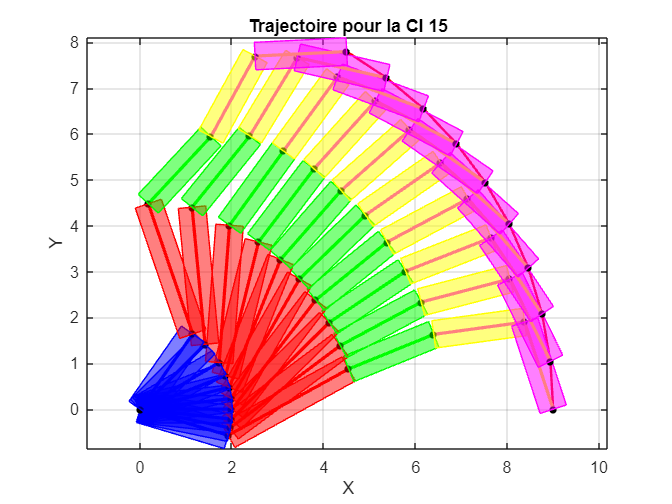

% Afficher la trajectoire
figure;
plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
axis equal; % Pour que l'échelle des axes soit égale
xlabel('X');
ylabel('Y');
title(['Trajectoire pour la CI ', num2str(data_for_ci(1))]);
grid on;
hold on;


% Pour chaque configuration initiale avec des solutions filtrées
for i = 1:size(solutions_filtrees_CI_complete, 1)
    % Extraire les données pour cette configuration initiale
    data_for_ci = solutions_filtrees_CI_complete(i, :);

    %% Convertir les angles de degrés en radians et les restreindre dans l'intervalle [0, 2*pi]
    theta1 = mod(deg2rad(data_for_ci(3)), 2*pi);
    theta2 = mod(deg2rad(data_for_ci(4)), 2*pi);
    theta3 = mod(deg2rad(data_for_ci(5)), 2*pi);
    theta4 = mod(deg2rad(data_for_ci(6)), 2*pi);
    theta5 = mod(deg2rad(data_for_ci(7)), 2*pi);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration initiale
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'HandleVisibility', 'off'); % Segment OA
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'HandleVisibility', 'off'); % Segment AB
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'HandleVisibility', 'off'); % Segment BC
    plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'HandleVisibility', 'off'); % Segment CD
    plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'HandleVisibility', 'off'); % Segment DE
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'HandleVisibility', 'off'); % Marques pour les articulations
    % Ajouter des rectangles autour des segments
    rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
    drawSegmentRectangle(O, A, rectWidth, 'b');
    drawSegmentRectangle(A, B, rectWidth, 'r');
    drawSegmentRectangle(B, C, rectWidth, 'g');
    drawSegmentRectangle(C, D, rectWidth, 'y');
    drawSegmentRectangle(D, E, rectWidth, 'm');
    % Mettre en pause pour une durée appropriée
    pause(0.1); % Changer cette valeur pour ajuster la vitesse de l'animation
end

function singularite = check_singularities(theta_solutions, a1, a2, a3, a4, a5)
    % Initialisation du vecteur indiquant la singularité pour chaque configuration
    singularite = false(size(theta_solutions, 1), 1);
  
    % Boucle sur toutes les solutions de theta
    for i = 1:size(theta_solutions, 1)
        % Extraire les valeurs de theta
        theta = theta_solutions(i, :);
        % Extraire les valeurs de theta individuellement
        theta1 = theta(1);
        theta2 = theta(2);
        theta3 = theta(3);
        theta4 = theta(4);
        theta5 = theta(5);
        
        % Calculer les dérivées partielles
        dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
        dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
        dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        % Construire la Jacobienne
        J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
        
        % Vérifier le rang de la matrice jacobienne
        if rank(J) < min(size(J))
            % Indiquer que cette configuration est singulière
            singularite(i) = true;
        end
       
    end
end

function in_workspace = point_in_workspace(x, y, points_atteign, K)
    % Vérifie si le point (x, y) est dans l'espace de travail du robot
    in_workspace = inpolygon(x, y, points_atteign(K, 1), points_atteign(K, 2));
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, theta_prev)

    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
    
    % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];
    
     % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        
        
        % Initialiser les angles d'articulation avec les valeurs précédentes
        theta1 = theta_prev(1);
        theta2 = theta_prev(2);
        theta3 = theta_prev(3);
        theta4 = theta_prev(4);
        theta5 = theta_prev(5);

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))));

            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
                 dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Mettre à jour les angles d'articulation précédents pour le prochain point de trajectoire
            theta_prev = [theta1, theta2, theta3, theta4, theta5];
            
            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
        end
    end
end
